figure out stats on the nascent rings

fname = 'Fig1h_kymo_all_tracks_global_ringtype_iMedFilt_VerCINI data.csv';
T=readtable(fname);
%assign unique id to each ring
T.id=zeros(size(T.n));
id=1;
T.id(1)=1;
for ii=2:numel(T.id)
    if(T.ROI_(ii)-T.ROI_(ii-1)<0)
        id=id+1;
    end
    T.id(ii)=id;
end
Tnascent=T(T.IsNascent==1,:);
nTrack=max(Tnascent.id);
%average # of tracks:
ringStat=table;
id=unique(Tnascent.id);
n=numel(id);
ringDiam=[];
ringNTrack=[];
for ii=1:n
    ringCur=Tnascent(Tnascent.id==id(ii),:);
    ringDiam(ii,1)=ringCur.DiameterNm(1);
    ringNTrack(ii,1)=size(ringCur,1);
end
ringStat.Diam=ringDiam;
ringStat.NTrack=ringNTrack;
median(ringStat.Diam)

ans = 878.3885

median(ringStat.NTrack)

ans = 6

mean(ringStat.NTrack)

ans = 5.8251

var(ringStat.NTrack)

ans = 4.4198

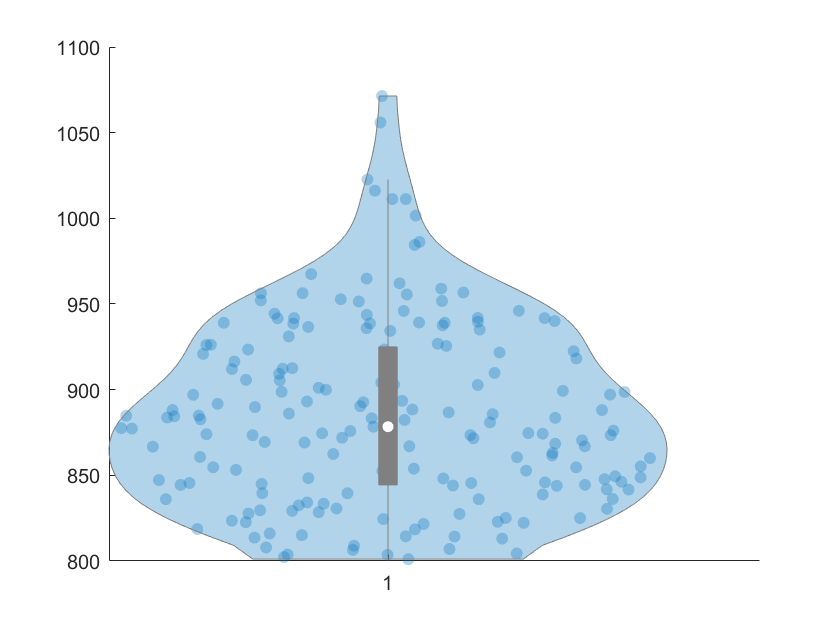

figure;
violinplot(ringStat.Diam);

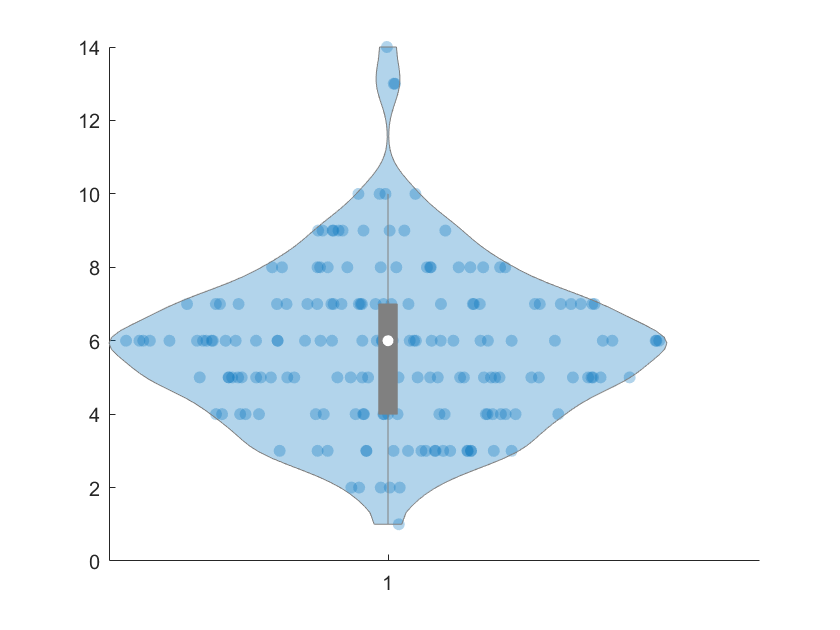

figure
violinplot(ringStat.NTrack);

non-nascent rings

Tother=T(T.IsNascent~=1,:);
nTrack=max(Tother.id);
%average # of tracks:
ringStat2=table;
id=unique(Tother.id);
n=numel(id);
ringDiam=[];
ringNTrack=[];
for ii=1:n
    ringCur=Tother(Tother.id==id(ii),:);
    ringDiam(ii,1)=ringCur.DiameterNm(1);
    ringNTrack(ii,1)=size(ringCur,1);
end
ringStat2.Diam=ringDiam;
ringStat2.NTrack=ringNTrack;
median(ringStat2.Diam)

ans = 795.5506

median(ringStat2.NTrack)

ans = 6

mean(ringStat2.NTrack)

ans = 6.0699

var(ringStat2.NTrack)

ans = 3.4581

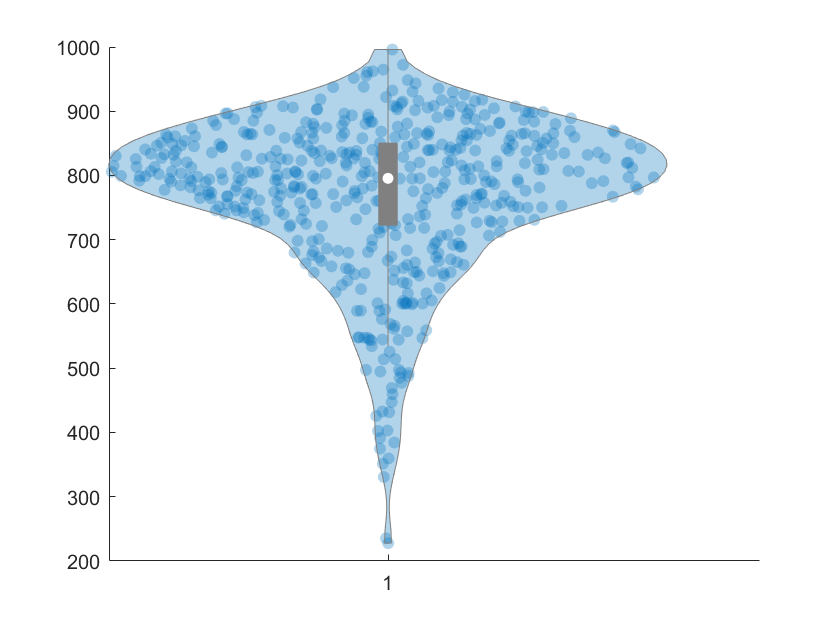

figure;
violinplot(ringStat2.Diam);

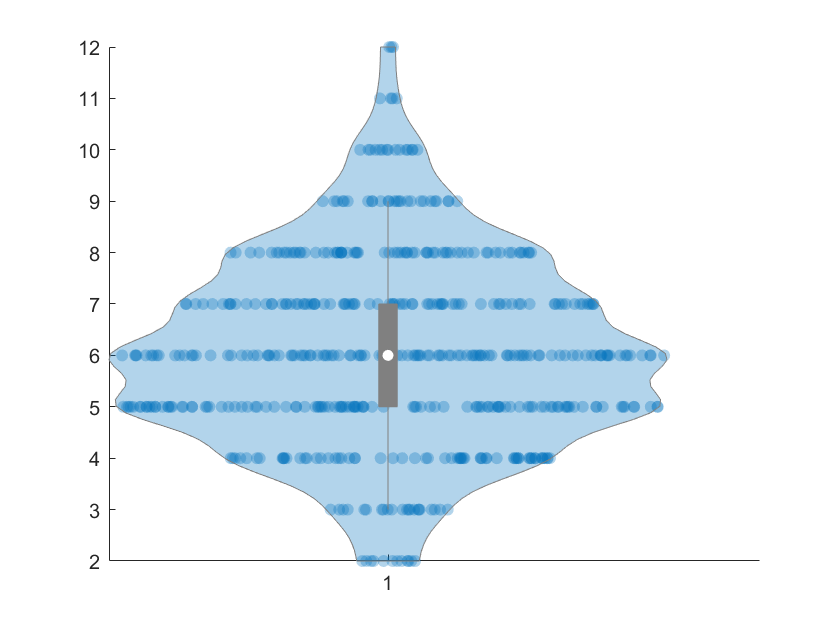

figure
violinplot(ringStat2.NTrack);

next we need:

- average filament intensity

- average background intensity and ring shape parameters

- gain of the camera